clear; clc;

% /functions path containing all fun
addpath('functions');

% Initialize parameters
params = initializeParameters();

                 Gaussian-Hermite Quadrature
----------------------------------------------------------------
Quadrature Nodes:   [-0.7071;0.7071]
Quadrature Weights: [0.8862;0.8862]
Dimensions:         2 nodes
----------------------------------------------------------------
                    Constellation Points
----------------------------------------------------------------
Points:             [-1 1]
Dimensions:         2 points
Average Energy:     1 (normalized)
----------------------------------------------------------------
                  Probability Distribution
----------------------------------------------------------------
Distribution:       [0.5 0.5]
Dimensions:         2 probabilities
Sum of Prob:        1


% Run E0 computation
[rho_values, Eo_rho] = computeE0(params);

                    Computing E0(ρ) Function
----------------------------------------------------------------
Initializing computation matrices
Computing E0 for 1000 points
----------------------------------------------------------------
E0(ρ) values:
[0 0.0008051 0.00161 0.002414 0.003218 0.004021 0.004824 0.005626 0.006429 0.00723 0.008031 0.008832 0.009632 0.01043 0.01123 0.01203 0.01283 0.01363 0.01443 0.01522 0.01602 0.01682 0.01761 0.01841 0.0192 0.02 0.02079 0.02159 0.02238 0.02317 0.02396 0.02476 0.02555 0.02634 0.02713 0.02792 0.02871 0.0295 0.03029 0.03108 0.03187 0.03265 0.03344 0.03423 0.03502 0.0358 0.03659 0.03737 0.03816 0.03894 0.03973 0.04051 0.04129 0.04208 0.04286 0.04364 0.04442 0.0452 0.04599 0.04677 0.04755 0.04833 0.0491 0.04988 0.05066 0.05144 0.05222 0.05299 0.05377 0.05455 0.05532 0.0561 0.05687 0.05765 0.05842 0.0592 0.05997 0.06074 0.06152 0.06229 0.06306 0.06383 0.0646 0.06537 0.06614 0.06691 

% Plot results
plotE0(rho_values, Eo_rho, params);

                       E0(ρ) Plot Analysis
----------------------------------------------------------------
Maximum E0 value: 0.6273
E0 at ρ = 0: 0.0000
E0 at ρ = 1: 0.6273


                    Optimization Parameters
----------------------------------------------------------------
Rate (R): 0.5 bits/channel use
----------------------------------------------------------------
Optimization Results:
Optimal ρ: 0.9089
Maximum value: 0.1284
E0 at optimal ρ: 0.5829


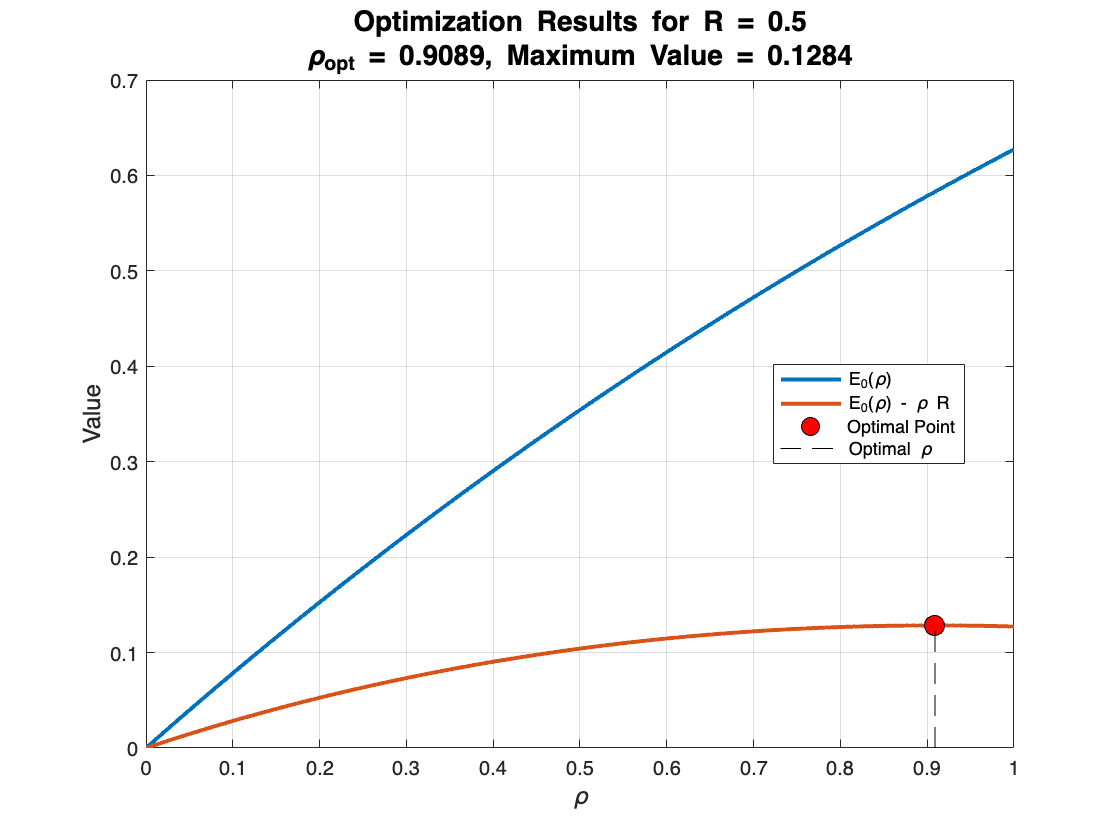

% Run constellation performance test
% performanceTest(params);
% Perform optimization
R = 0.5;
optimizeRho(Eo_rho, rho_values, R);